**0.1 Read in the data**

clear
book_fname = 'goblet_book.txt';
fid = fopen(book_fname, 'r');
book_data = fscanf(fid, '%c');
fclose(fid);

%Different characters in the book
book_chars = unique(book_data);
K = length(book_chars); %dimensionnality of the output of the RNN

%initialize map containers
values = 1:K;
key = num2cell(book_chars);
char_to_ind = containers.Map(key, values);
ind_to_char =  containers.Map(values, key);

**0.2 Set hyper-parameters & initialize the RNN's parameters**

m = 100; %dimensionality of its hidden state
eta = .1; % learning rate
seq_length = 25; %length of the input sequence
sig = .01;

%bias vectors
RNN.b = zeros(m,1);
RNN.c = zeros(K,1);

%Weight matrices 
RNN.U = randn(m, K)*sig;
RNN.W = randn(m, m)*sig;
RNN.V = randn(K, m)*sig;
M.U = zeros(size(RNN.U));
M.W = zeros(size(RNN.W));
M.V = zeros(size(RNN.V));
M.b = zeros(size(RNN.b));
M.c = zeros(size(RNN.c));

**0.3 Synthesize text from the randomly initialized RNN**

%see function

**0.4 Implement the forward & backward pass of back-prop**

x = zeros(1, length(book_data));
for i = 1:length(book_data)
    x(i) = char_to_ind(book_data(i)); 
end

vec = ind2vec(x);
data = full(vec);

X = data(:,1:seq_length);
Y = data(:, 2:seq_length+1);

h0 = zeros(size(RNN.W, 1), 1);
n = 25;
[~, a, h, ~, p] = Forward(RNN, X(:,1:n), Y(:, 1:n), h0, n, K, m);

% Check gradients
 gradients = ComputeGradients(RNN, X(:,1:n), Y(:, 1:n), a, h, p, n,m);
 numgrads = ComputeGradsNum(X(:,1:n), Y(:, 1:n),RNN, 1e-4);

Computing numerical gradient for
Field name: b
Computing numerical gradient for
Field name: c
Computing numerical gradient for
Field name: U
Computing numerical gradient for
Field name: W
Computing numerical gradient for
Field name: V


eps = 1e-6;

 for f = fieldnames(RNN)'
    num_g  = numgrads.(f{1});
    g = gradients.(f{1});
     num = abs(num_g - g);
     deno =abs(num_g)  + abs(g);
    %check = sum(num(:))/max(eps, sum(deno(:)));
    check = max(max(abs(num_g-g)));
    disp(['Gradient of : ' f{1}]);
    
    if check <=1e-5
        disp(['Correct gradients: ' num2str(check)]);
    else
        disp(['Incorrect gradients: ' num2str(check)]);
    end
end

Gradient of : b


Incorrect gradients: 1.9824e-05


Gradient of : c


Correct gradients: 3e-06


Gradient of : U


Incorrect gradients: 0.045131


Gradient of : W


Incorrect gradients: 0.0034922


Gradient of : V


Incorrect gradients: 0.058621


**0.5 Training your RNN using AdaGrad**

m = 100; %dimensionality of its hidden state
eta = .1; % learning rate
seq_length = 25; %length of the input sequence
sig = .01;

%bias vectors
RNN.b = zeros(m,1);
RNN.c = zeros(K,1);

%Weight matrices 
RNN.U = randn(m, K)*sig;
RNN.W = randn(m, m)*sig;
RNN.V = randn(K, m)*sig;
M.U = zeros(size(RNN.U));
M.W = zeros(size(RNN.W));
M.V = zeros(size(RNN.V));
M.b = zeros(size(RNN.b));
M.c = zeros(size(RNN.c));

x = zeros(1, length(book_data));
for i = 1:length(book_data)
    x(i) = char_to_ind(book_data(i)); 
end

vec = ind2vec(x);
data = full(vec);

seq_length = 25;
iter = 1;
n_epochs = 3;
smooth_loss = [];
loss_s = 0;
hprev = []; 
min_loss = 500;

for i = 1:n_epochs
    iter
    [RNN, loss_s, min_RNN, min_h, min_iter, min_loss, M,iter] = AdaGrad(RNN, ...
        data,  seq_length, K, m, eta, iter, ind_to_char, loss_s(end), min_loss, M);
    smooth_loss = [smooth_loss, loss_s];
    
end

iter = 1

---------------------------------
    "iter = "    "1"    ", smooth_loss = "    "109.5441"

EykMDjW' lTE0,PEAzHORKLTno^nWPHu(JX'oR'w0rW_4:a'qrP"L'sq(DLYIn'jr3!Hxd!j9ib1G_Q?p3G/xD1tZH-üOXa3-_XAfyoq'jrAAYCjf•UIB?iMAhev,WKX6OT}/7G:Sy ?ggY0Byt!HJw? p3q;XGbuvhNJ rBLR?ü?6ZGjW-EEj!Jü4Y_Ag•;JsBYK}WL
---------------------------------
    "iter = "    "10000"    ", smooth_loss = "    "56.7239"

e  Roa the.
"I macet and in lrur thtit, soushe's hid and be rroring Hal  Ich Weare rooko hid Harryt whagh wituke- Madle bar, lusct ont aagum, the trleuy yo move- that! arg cupte a do teoblor's bice's;
---------------------------------
    "iter = "    "20000"    ", smooth_loss = "    "53.5606"

arry -"  heas.  Ron the ffouge lyad natt with baiked ther te pade Herre's way serous uted the do stombwancliog -on's - . . winges richad he Mrying Harry.
"Durtibign hizl unk in horry,". . to they hid 
---------------------------------
    "iter = "    "30000"    ", smooth_loss = "    "52.1843"

ey didn nech bitper 

iter = 44302

---------------------------------
    "iter = "    "50000"    ", smooth_loss = "    "51.8783"

." aFle agh hemaow beliys make sast, whous ain srakgry.  The splew irmen walade saat for't as -"
AThestk winger aid Mr.  Veay a As.  "
Azers avagint, owak he bpyed arl fime it frailvoting fintiof saza
---------------------------------
    "iter = "    "60000"    ", smooth_loss = "    "50.9051"

erey fouce on stingen in to low revers, ulha sas a buny.
"Be buid ayed they histale Gracing tage ous, werry ang hinsthibeess wenke tote youft!"
"Fulle of ersjudrel.  Selp hopl the waid, the bele at he
---------------------------------
    "iter = "    "70000"    ", smooth_loss = "    "50.2874"

oeted furpints was had de withuns.
"Yerrad wind encaly.
"Beened his Harry tho ooly ho -oostay,"  begwered saikecer.  Sh poteled Wovaon sim then diosde's Fe ofstar fore nobargey layerule n ug, nhar a h
---------------------------------
    "iter = "    "80000"    ", smooth_loss = "    "48.873"

orre the sase.
"I 

iter = 88603

---------------------------------
    "iter = "    "90000"    ", smooth_loss = "    "49.073"

er.  I's his poided upen and a fle, nolled, dule tom hom waske, the losmes wave tonded, in ouets and detedagore evaring lige and to hasas wapirfo had Highaked in cont hat forooyers she the fround out 
---------------------------------
    "iter = "    "100000"    ", smooth_loss = "    "50.1817"

as fon to hes tatle scake he'd wouldrick. Welsslembreding and sho on, and sulde bed tobirg's and toward teir hird for the rack thos berer, wremeng at the as saikn quecise Mast - his lesped cotfound, N
---------------------------------
    "iter = "    "110000"    ", smooth_loss = "    "48.1845"

ear thind had the tumedn the heroup, hen gittentey, givinw he.  I'rry, fion bry and couil that intery bett taten hid youd the and him that the by I warly buding thes lefreds that eams as, in chaindoy.
---------------------------------
    "iter = "    "120000"    ", smooth_loss = "    "48.172"

arry Hir a Sbeth

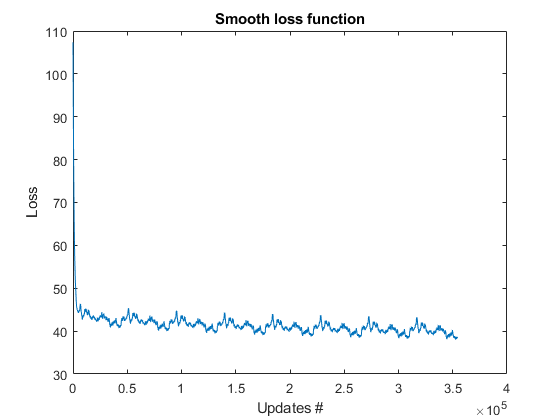

figure();
plot((1:length(smooth_loss)), smooth_loss);
xlabel('Updates #');
ylabel('Loss');
title('Smooth loss function');

text_length = 1000;
y = synthesize(min_RNN, min_h, data(:, 1), text_length, K);
c = [];
for i = 1:text_length
    c = [c ind_to_char(y(i))];
end
fprintf('\n');
disp(['iter = ' num2str(min_iter) ', minimum loss = ' num2str(min_loss)]);

iter = 352474, minimum loss = 38.0648


disp(c);

 Epply know this win reached .., nos think knewes's Moody with his win feer and she Madd, and Harry my brilack, and Moody, last edried sosel's a seevion when the vifiather.  "Volf sahand to the that crungle mape is I who just his proked the dark out."
"Madd.   Harry outy his shout.  The bovids a mrouch up niry out of the darking house.
"Sordy, and Skeeders hellsef.
"Peen to could rill his said rom!"
"Seaz'd Monne's worked My not hund Dumbledore it into costle was that coulded the happarch of sand . . . when Hermione ;ENTET

The leadly."
The eactericys to hisshemort," said Voldemort-lunger, fe'red his HOlTfrickers time around.  It bearts golding opened beying up at he time sindfiral intoblowarlust you deading to Skass Chisibber fest wince you did he smith Harry said of the hook around.  I scace.  He've to around hird fampeopus, so itades no through mazantusely they pished at his onchely grying ur douct his beached atongrafo dast mer in to the figot Ciss.  Creet spettuets?' Goody's re-  

**Functions**

function y = synthesize(RNN,h0, x0, n ,K)
    %The function will synthesize a sequence of characters using the current
    %parameter values in RNN.
    %h0 : hidden state at time 0
    %x0 : the first(dummy) input to the RNN
    %n : denotes the length of the sequence e want to generate
    W = RNN.W;
    U = RNN.U;
    V = RNN.V;
    b = RNN.b;
    c = RNN.c;
    h = h0;
    x = x0;
    y = zeros(1,n);
    for t= 1:n
        a = W*h + U*x + b;
        h = tanh(a);
        o = V*h + c;
        p = exp(o)/sum(exp(o)); 
        
        %Randomly select a character based on the output probability scores p
        cp = cumsum(p);
        a = rand;
        ixs = find(cp-a >0);
        ii = ixs(1);
        
        %generate the next output
        N = length(ii);
        x = zeros(K,N);
        for i = 1:N 
            x(ii(i),i) = 1; %One hot encoding of next input
        end
        y(t) = ii;
    end
end

function loss = ComputeLoss(X, Y , RNN, h)
    %COMPUTELOSS 
    n = size(X,2);
    loss = 0;

    for i = 1:n
        a = RNN.W*h + RNN.U*X + RNN.b;
        h = tanh(a);
        o = RNN.V*h + RNN.c;
        p = exp(o)/sum(exp(o)); 
        
        loss = loss - log(Y(:,i)'*p);
    end
end

function gradients = ComputeGradients(RNN, X, Y, a, h, p, n,m)
    W = RNN.W;
    V = RNN.V;
    g_h = zeros(n, m);
    g_a = zeros(n, m);  
    
    g = -(Y-p)';
    gradients.c = (sum(g))';
    gradients.V = g'*h(:, 2:end)';
    
    g_h(n,:) = g(n,:)*V;
    g_a(n, :) = g_h(n, :)*diag(1 - (tanh(a(:, n))).^2); 
    
    for t = (n-1):-1:1
        g_h(t, :) = g(t, :)*V + g_a(t+1, :)*W;
        g_a(t, :) = g_h(t, :)*diag(1 - (tanh(a(:, t))).^2);
    end
    
    gradients.b = (sum(g_a))';
    gradients.W = g_a'*h(:,1:end-1)';
    gradients.U = g_a'*X';
    
end

function [loss, a, h, o, p] = Forward(RNN, X, Y, h0, n, K, m)
    o = zeros(K, n);
    p = zeros(K, n);
    h = zeros(m, n);
    a = zeros(m, n);
    ht = h0;
    loss = 0;
    
    for t = 1:n
        at = RNN.W*ht +RNN.U*X(:,t) + RNN.b;
        a(:,t) = at;
        ht = tanh(at);
        h(:,t) = ht;
        o(:,t) = RNN.V*ht + RNN.c;
        p(:,t) = exp(o(:,t))/sum(exp(o(:,t)));
        
        loss = loss - log(Y(:,t)'*p(:,t));
    end
    h = [h0, h];
end

function [RNN,M] = Backward(RNN, X, Y, a, h, p,eta, n, m,M)
    gradients = ComputeGradients(RNN, X, Y, a, h, p, n, m);
    eps = 1e-8;

    for f=fieldnames(gradients)'
        gradients.(f{1}) = max(min(gradients.(f{1}), 5), -5);
    end
    
    for f = fieldnames(RNN)'
        % AdaGrad
        M.(f{1}) = M.(f{1}) + gradients.(f{1}).^2;
        RNN.(f{1}) = RNN.(f{1}) - eta*(gradients.(f{1})./(M.(f{1}) + eps).^(0.5));
        %RNN.(f{1}) = RNN.(f{1}) - eta*(gradients.(f{1}));
    end
end

function [RNN, loss_s, min_RNN, min_h, min_iter, min_loss, M,iter] = AdaGrad(RNN, data,  n, K, m, eta, iter, ind_to_char, smooth_loss, min_loss, M)
    %AdaGrad algorithm
    e =1;
    len = 200;
    loss_s = [];
    
    while e <= length(data) -n -1
        Xbatch = data(:, e: e+n-1);
        Ybatch = data(:, e +1 :e+n);
        if e ==1
            hprev = zeros(m,1);
        else
            hprev = h(:,end); 
        end
        
        [loss, a, h, ~, p] = Forward(RNN, Xbatch, Ybatch, hprev, n, K, m);
        [RNN, M] = Backward(RNN, Xbatch, Ybatch, a,h, p, eta, n, m, M);
        
        if iter == 1 && e ==1 
            %initialize first ite
            smooth_loss = loss;
        end
        smooth_loss = 0.999*smooth_loss + 0.001*loss;
        
        if smooth_loss < min_loss
            min_RNN = RNN;
            min_h = hprev;
            min_iter = iter;
            min_loss = smooth_loss;
        end
        
        loss_s = [loss_s, smooth_loss];
        
        if iter == 1 || mod(iter, 10000) ==0
            y = synthesize(RNN, hprev, data(:,1), len, K);
            c = [];
            for i = 1:len
                c = [c ind_to_char(y(i))];
            end
            disp ("---------------------------------");
            disp (["iter = " iter ", smooth_loss = " smooth_loss]);
            disp(c);
        end
        iter = iter +1;
        e = e + n;
    end
end
